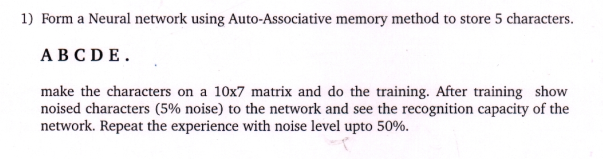

A = [   -1	1	1	1	1	1	-1;
        -1	1	1	1	1	1	-1;
        -1	1	1	-1	1	1	-1;
        -1	1	1	-1	1	1	-1;
        -1	1	1	-1	1	1	-1;
        -1	1	1	1	1	1	-1;
        -1	1	1	1	1	1	-1;
        -1	1	1	-1	1	1	-1;
        -1	1	1	-1	1	1	-1;
        -1	1	1	-1	1	1	-1;];

B = [   -1	1	1	1	1	1	-1;
        -1	1	1	-1	-1	1	 -1;
        -1	1	1	-1	-1	1	 -1;
        -1	1	1	-1	-1	1	 -1;
        -1	1	1	1	1	1	-1;
        -1	1	1	-1	-1	1	 -1;
        -1	1	1	-1	-1	1	 -1;
        -1	1	1	-1	-1	1	 -1;
        -1	1	1	-1	-1	1	 -1;
        -1	1	1	1	1	1	-1;];

C = [   -1	1	1	1	1	1	-1 ;
        -1	1	1	1	1	1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	1	1	1	-1 ;
        -1	1	1	1	1	1	-1 ;];

D = [   -1	1	1	1	1	1	-1 ;
        -1	1	1	1	1	1	 -1 ;
        -1	1	1	-1	-1	1	 -1 ;
        -1	1	1	-1	-1	1	 -1 ;
        -1	1	1	-1	-1	1	 -1 ;
        -1	1	1	-1	-1	1	 -1 ;
        -1	1	1	-1	-1	1	 -1 ;
        -1	1	1	-1	-1	1	 -1 ;
        -1	1	1	1	1	1	 -1 ;
        -1	1	1	1	1	1	-1 ;];

E =[    -1	1	1	1	1	1	-1 ;
        -1	1	1	1	1	1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	1	1	1	-1 ;
        -1	1	1	1	1	1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	-1	-1	-1	-1 ;
        -1	1	1	1	1	1	-1 ;
        -1	1	1	1	1	1	-1 ;];

input = containers.Map({1,2,3,4,5},{A,B,C,D,E});

% training
w = zeros(70,70);
for i = 1:5
    a = reshape(input(i),[],1) ;
    w = w + a*a' ;
end

output = containers.Map('KeyType','int32','ValueType','any');
fprintf("At 0 percent noise");

At 0 percent noise

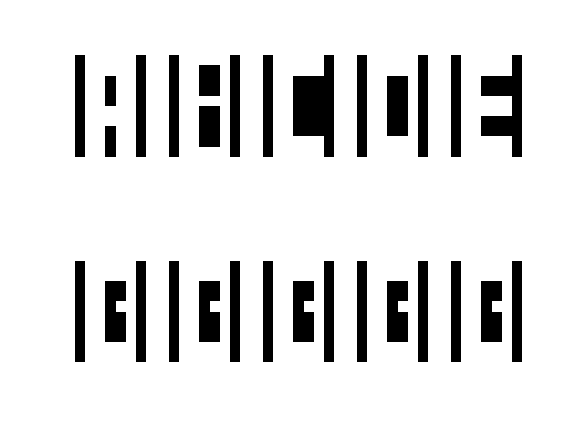

for j = 1:5
    a = reshape(input(j),[],1);
    out = recall(a,w);
    output(j) = out ;
end
for i = 1:5
    subplot(2,5,i),imshow(input(i));
end

for i = 1:5
    out = reshape(output(i),10,7);
    subplot(2,5,5+i),
    imshow(out);
end

input_5 = containers.Map({1,2,3,4,5},{noise(A,5),noise(B,5),noise(C,5),noise(D,5),noise(E,5)});


fprintf("With %d percent noise",5);

With 5 percent noise

output_5 = containers.Map('KeyType','int32','ValueType','any');
for j = 1:5
    a = reshape(input_5(j),[],1);
    out = recall(a,w);
    output_5(j) = out ;
end

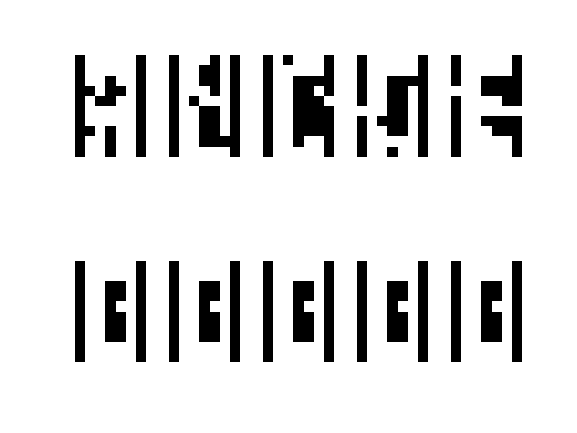

for i = 1:5
    subplot(2,5,i),imshow(input_5(i));
end

for i = 1:5
    out = reshape(output_5(i),10,7);
    subplot(2,5,5+i),
    imshow(out);
end

fprintf("With %d percent noise",10);

With 10 percent noise

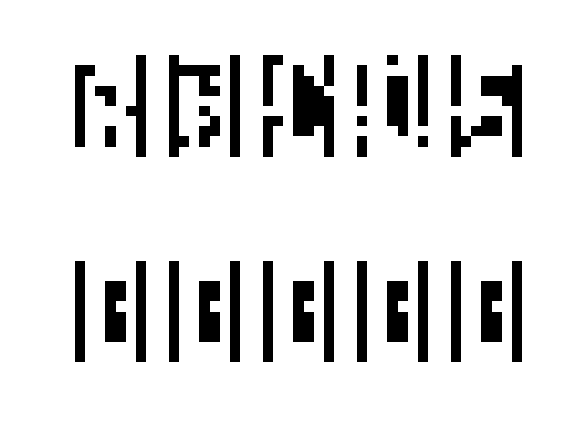

input_10 = containers.Map({1,2,3,4,5},{noise(A,10),noise(B,10),noise(C,10),noise(D,10),noise(E,10)});
output_10 = containers.Map('KeyType','int32','ValueType','any');
for j = 1:5
    a = reshape(input_10(j),[],1);
    out = recall(a,w);
    output_10(j) = out ;
end
for i = 1:5
    subplot(2,5,i),imshow(input_10(i));
end

for i = 1:5
    out = reshape(output_10(i),10,7);
    subplot(2,5,5+i),
    imshow(out);
end

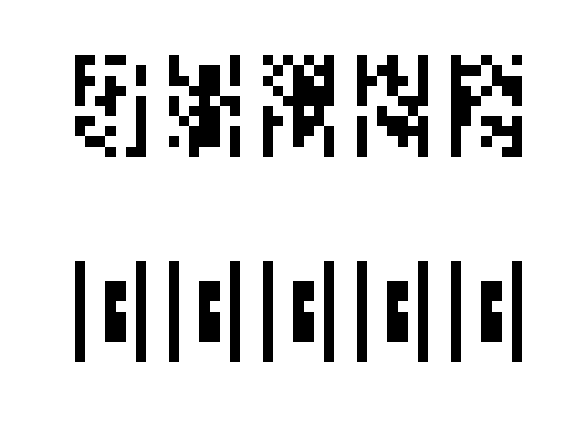

input_25 = containers.Map({1,2,3,4,5},{noise(A,25),noise(B,25),noise(C,25),noise(D,25),noise(E,25)});
output_25 = containers.Map('KeyType','int32','ValueType','any');
for j = 1:5
    a = reshape(input_25(j),[],1);
    out = recall(a,w);
    output_25(j) = out ;
end
for i = 1:5
    subplot(2,5,i),imshow(input_25(i));
end

for i = 1:5
    out = reshape(output_25(i),10,7);
    subplot(2,5,5+i),
    imshow(out);
end

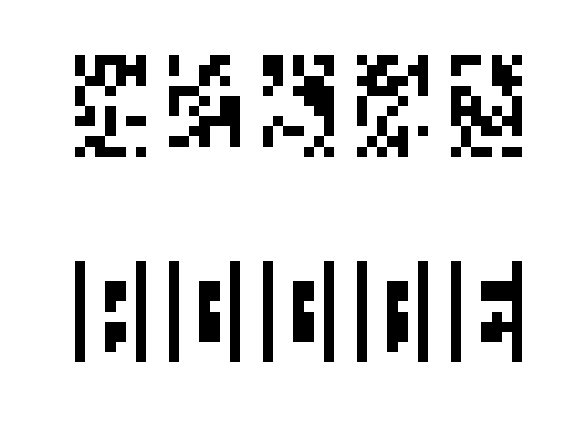

input_50 = containers.Map({1,2,3,4,5},{noise(A,50),noise(B,50),noise(C,50),noise(D,50),noise(E,50)});
output_50 = containers.Map('KeyType','int32','ValueType','any');
for j = 1:5
    a = reshape(input_50(j),[],1);
    out = recall(a,w);
    output_50(j) = out ;
end
for i = 1:5
    subplot(2,5,i),imshow(input_50(i));
end

for i = 1:5
    out = reshape(output_50(i),10,7);
    subplot(2,5,5+i),
    imshow(out);
end

function k = check(out,w,x)
    if out == x
        k = 1;
        return;
    end
    out2 = recall(out',w);
    if out2 == out
        k = 0;
        return;
    end
    k = check(out2,w,x) ;
end


function out = recall(a,w)
    out = a'*w ;
    for i = 1:size(out,2)
        if out(i) > 0
            out(i) = 1;
        elseif out(i) < 0
            out(i) = -1;
        else
            out(i) = a(i);
        end
    end
end

function A = noise(X,per)
    k = numel(X);
    n = ceil((k*per)/100) ;
    index = randi(k,n,1);
    for i = index
        X(i) = X(i)*-1 ;
    end
    A=X;
end